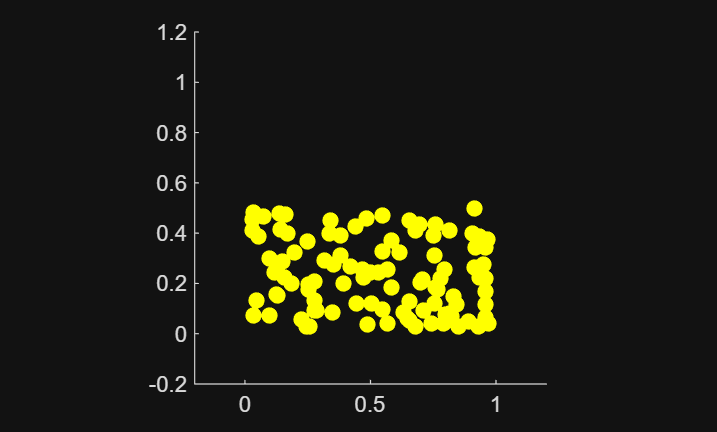


Xdim = 1;
Ydim = 1;
Ndim = 100;
Tdim = 1000;
IGDim = 1;
R = .03;
WFC = 1;
dt = .00001;
K=10;
BD = .2;

PrxD = clip(Xdim*rand(1,Ndim),R,Xdim-R);
PryD = clip(.5*Ydim*rand(1,Ndim),R,Ydim-R);
PvxD = 5*rand(1,Ndim);
PvyD = 5*rand(1,Ndim);

Prx = (PrxD);
Pry = (PryD);
Pvx = (PvxD);
Pvy = (PvyD);

P1 = scatter(Prx,Pry,2^9,"yellow","filled");
% hold on
axis equal
xlim([-BD Xdim+BD])
ylim([-BD Ydim+BD])
currentunits = get(gca,'Units');
set(gca, 'Units', 'Points');
axpos = get(gca,'Position');
set(gca, 'Units', currentunits);
markerWidth = R/diff(xlim)*axpos(3); % Calculate Marker width in points
set(P1, 'SizeData', markerWidth^2)

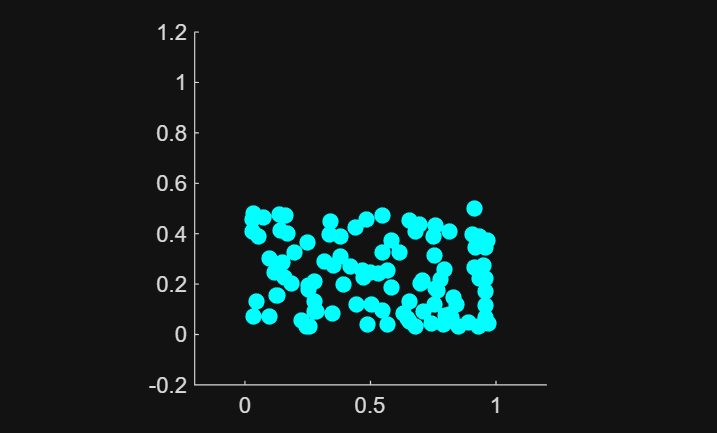


% for i=1:1000
% BIC = min(((ones(1,Ndim).*Prx'-ones(Ndim,1).*Prx).^2+(ones(1,Ndim).*Pry'-ones(Ndim,1).*Pry).^2-2*R^2*(1-eye(Ndim))),0);
% Prx = Prx - sum(-sqrt(-BIC).*sign(ones(1,Ndim).*Prx'-ones(Ndim,1).*Prx)*.25,2)';
% Pry = Pry - sum(-sqrt(-BIC).*sign(ones(1,Ndim).*Pry'-ones(Ndim,1).*Pry)*.25,2)';
% end


P2 = scatter(Prx,Pry,2^9,"cyan","filled");
axis equal
xlim([-BD Xdim+BD])
ylim([-BD Ydim+BD])
currentunits = get(gca,'Units');
set(gca, 'Units', 'Points');
axpos = get(gca,'Position');
set(gca, 'Units', currentunits);
markerWidth = R/diff(xlim)*axpos(3); % Calculate Marker width in points
set(P2, 'SizeData', markerWidth^2)